# Offline Classification From Features

Neurotechnology, Brains and Machines 2023 (shell code my Sam Michalka)

This shell code expects that you have:

-  data with features already extracted in a variable called feature_table

- labels for the data in a variable called labels. 

The features should be in a table with the rows equal to the number of trials and the columns equal to the number of features. You can select a subset of features in the code below.

clear

Indicate if your test data is in a separate file or partitioned from the train data.

Make a list of files to load. If this has two things, the code will assume it is the train features followed by the test features. If it has one item, it will assume they are training featues and run a train-test split.  

If you want to use resubstitution, put the same training data twice (once as train, once as test).

%filesToLoad = {"anotherday_feature_table.mat"}; % you'll need to change this name

%filesToLoad = {"latest_feature_table.mat","latest_feature_table.mat"}; %Do this for resubstitution

filesToLoad = {"example_train_feature_table.mat", "example_test_feature_table.mat"};
%filesToLoad = {"train_feature_table.mat", "anotherday_feature_table.mat"};


#### Select which features you want. selected_features is the indices of these features. You can get fancy and use contains() if you want to pull them out by name.

% temporarily load the feature data to get selected features
load(filesToLoad{1})

Print out all the feature names

feature_table.Properties.VariableNames

ans = 1×28 cell array
    {'variance_Ch1'}    {'variance_Ch2'}    {'variance_Ch3'}    {'variance_Ch4'}    {'waveformlength_Ch1'}    {'waveformlength_Ch2'}    {'waveformlength_Ch3'}    {'waveformlength_Ch4'}    {'meanabsvalue_Ch1'}    {'meanabsvalue_Ch2'}    {'meanabsvalue_Ch3'}    {'meanabsvalue_Ch4'}    {'rootmeansquare_Ch1'}    {'rootmeansquare_Ch2'}    {'rootmeansquare_Ch3'}    {'rootmeansquare_Ch4'}    {'willisonamp_Ch1'}    {'willisonamp_Ch2'}    {'willisonamp_Ch3'}    {'willisonamp_Ch4'}    {'integratedemg_Ch1'}    {'integratedemg_Ch2'}    {'integratedemg_Ch3'}    {'integratedemg_Ch4'}    {'meanpower_Ch1'}    {'meanpower_Ch2'}    {'meanpower_Ch3'}    {'meanpower_Ch4'}


Select a subset of features (or all of them)

%selected_features = 1:size(feature_table,2); % This selects all features
selected_features = [5 6 7 8 13 14 15 16]; %This selects the waveformlength and rootmeansquare
%selected_features = [21 22 23 24]; %This selects integratedemg


clearvars feature_table labels  % you just temporarily loaded these in to
%get the feature names, delete them so you don't get confused

includedFeatures = {'waveformlength', 'rootmeansquare'}

includedFeatures = 1×2 cell array
    {'waveformlength'}    {'rootmeansquare'}


label_rps = string(["rock","paper","scissors"]);

## Load the feature data and put into X and y matrices

Look inside the function below to set things like train-test split.

[X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features);

## Build a classifier and do k-fold cross-validation

% Perform cross-validation
KFolds = 5;
cvp_kfold = cvpartition(y_train, 'KFold', KFolds);

% Make empty vector to store predictions from k-fold cross-validation
validation_predictions = NaN(length(y_train),1);

% Loop through all the folds
for fold = 1:KFolds
    % Within each partition, assign the data for that fold to the
    % cross-validation training data
    kfold_partial_data_X_train = X_train(cvp_kfold.training(fold), :);
    kfold_partial_data_y_train = y_train(cvp_kfold.training(fold), :);
    
    % Within each partition, assign the data for that fold to the
    % cross-validation validation (testing) data
    kfold_partial_data_X_val = X_train(cvp_kfold.test(fold), :);
    %kfold_partial_data_y_val = y_train(cvp_kfold.test(fold), :);

    % Build a temporary model for this subset of the data (k-1)/k
    kfold_classifier = createClassifier(kfold_partial_data_X_train,kfold_partial_data_y_train);

    % Make predictions with the kfold_classifier  (temporary classifier on
    % subset of data)
    kfold_predictions = kfold_classifier.predict(kfold_partial_data_X_val);

    % Store predictions in the original order
    validation_predictions(cvp_kfold.test(fold), :) = kfold_predictions;
end

% Calculate cross-validation metrics
[validation_accuracy, matrix] = calculateMetrics(y_train, validation_predictions)

validation_accuracy = 0.9722

matrix =     59     0     1
     0    60     0
     3     1    56


## Build a classifer on all of the training data

By making a createClassifier function, we can better ensure that the classifier we're using for the model and for cross-validation are the same. You can also make this into a function with other options (like which classifier to use or some paramter in the classifier that you want to vary).

% Create a classifier  
currentClassifier = createClassifier(X_train, y_train);

## Use classifier to predict on training data (resubstitution)

y_train_predictions = currentClassifier.predict(X_train);
[train_accuracy, matrix, precision, recall, f1Scores] = calculateMetrics(y_train, y_train_predictions)

train_accuracy = 0.9889

matrix =     60     0     0
     0    60     0
     1     1    58


precision = function_handle with value:
    @(confusionMat)diag(confusionMat)./sum(confusionMat,2)


recall = function_handle with value:
    @(confusionMat)diag(confusionMat)./sum(confusionMat,1)'


f1Scores = function_handle with value:
    @(confusionMat)2*(precision(confusionMat).*recall(confusionMat))./(precision(confusionMat)+recall(confusionMat))


save("example_final_train_accuracy.mat","train_accuracy");
mean(f1Scores(matrix))

ans = 0.9888

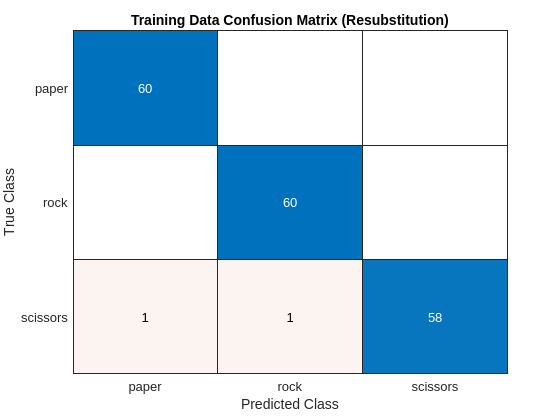

training_confusion_chart = confusionchart(matrix, label_rps);
title("Training Data Confusion Matrix (Resubstitution)");
exportgraphics(gcf, "example_final_train_confusion.png", 'Resolution', 300)

## Use classifier to predict on test data

y_test_predictions = currentClassifier.predict(X_test);
[test_accuracy, matrix, precision, recall, f1Scores]  = calculateMetrics(y_test, y_test_predictions)

test_accuracy = 0.9750

matrix =     40     0     0
     1    39     0
     2     0    38


precision = function_handle with value:
    @(confusionMat)diag(confusionMat)./sum(confusionMat,2)


recall = function_handle with value:
    @(confusionMat)diag(confusionMat)./sum(confusionMat,1)'


f1Scores = function_handle with value:
    @(confusionMat)2*(precision(confusionMat).*recall(confusionMat))./(precision(confusionMat)+recall(confusionMat))


save("example_final_test_accuracy.mat","test_accuracy");
mean(f1Scores(matrix))

ans = 0.9752

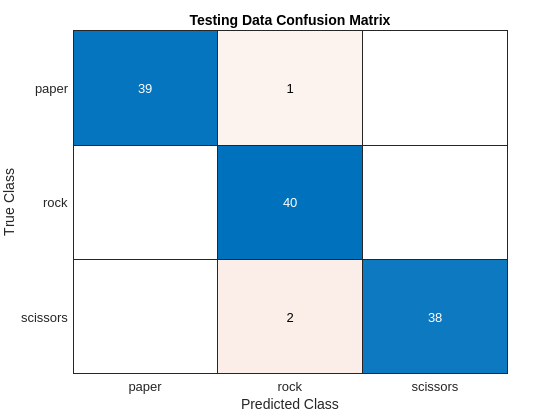


testing_confusion_chart = confusionchart(matrix, label_rps);
title("Testing Data Confusion Matrix");
exportgraphics(gcf, "example_final_test_confusion.png", 'Resolution', 300)

# Helper functions

The code after this are functions that you can use and modify. By using functions to do more of the detailed work, we can better see the big picture above. And, we can better reuse the same code.

## Create X_train, y_train, X_test, and y_test. Configure train-test split here.

function [X_train, y_train, X_test, y_test] = featuresTo_X_y_train_test(filesToLoad, selected_features)


True if you have separate test data to load (or just use all the train data again), false if you want to partition it from the data.

    if size(filesToLoad,2) == 2
        isSeparateTestData = true;
    elseif size(filesToLoad,2) == 1
        isSeparateTestData = false;
    else 
        error("Wrong number of files to load.")
    end
    
    %

Load the training data. This is expecting your features to be in a table called feature_table. 

    load(filesToLoad{1})

#### If separate test data

    if isSeparateTestData   
        % Put the train data into X and y  
        X_train = feature_table(:,selected_features);
        y_train = labels;
    
    
        % If you just want to use your train data again (resubstitution), just
        % get rid of the load part and repeat the step above.
    
        % Load the test data (here, it's the same file.. so fix this)
        load(filesToLoad{2});
    
        % Put the test data into X and y  
        % You might need to change variable names here
        X_test = feature_table(:,selected_features);
        y_test = labels;

#### If split the train / test data from one file

    else
        % If you want to partition your data into train and test
        holdout_proportion_test = 0.25;
        try 
            % If it exists, Load a saved partition from last time (so you don't keep
            % shufflig which dat is your train and test)
            load("lastCVpartition.mat")
            disp("loading prior training-test partition")
            if cvtt.NumObservations ~= length(labels) || cvtt.TestSize/cvtt.NumObservations ~= holdout_proportion_test
                warning('Loaded cv partition does not match number of observations, delete or rename and rerun, making a temporary new one')
                
                cvtt = cvpartition(labels,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            end
        catch
            cvtt = cvpartition(labels,"HoldOut",holdout_proportion_test); % Decimal is how much to hold out for test
            save("./lastCVpartition.mat","cvtt");
            disp('Making new training-test partiton')
        end
        
        % Train data
        X_train = feature_table(training(cvtt),selected_features);
        y_train = labels(training(cvtt));
    
        %Test datac
        X_test = feature_table(test(cvtt),selected_features);
        y_test = labels(test(cvtt));
    end
end

## Build a model based on data

There are various models that you can use here for 3 classes. You can add more details / parameters here.

function [theClassifier] = createClassifier(dataIn, labelsIn)
    
    % Linear discriminant analysis
    theClassifier = fitcdiscr(dataIn,labelsIn);

    % Decision tree
    %theClassifier = fitctree(dataIn,labelsIn)

    % fitcknn does k-nearest neighbors
    %theClassifier = fitcknn(dataIn,labelsIn,...
    %    "NumNeighbors",3);

end

## Calculate key metrics

You can put your other key metrics (such as F1 score) in here. You'll need to add more outputs to your function. 

function [accuracy, matrix, precision, recall, f1Scores] = calculateMetrics(true_labels, predicted_labels)
    
    accuracy = sum(true_labels == predicted_labels) / length(true_labels);
    matrix = confusionmat(true_labels, predicted_labels);

    % Extracting measures of goodness from a confusion matrix
    % Source: https://stackoverflow.com/questions/22915003/is-there-any-function-to-calculate-precision-and-recall-using-matlab
    precision = @(confusionMat) diag(confusionMat)./sum(confusionMat,2);
    recall = @(confusionMat) diag(confusionMat)./sum(confusionMat,1)';
    f1Scores = @(confusionMat) 2*(precision(confusionMat).*recall(confusionMat))./(precision(confusionMat)+recall(confusionMat));
    
end